clear all
clc, close all;
FIRST_MEASUREMENT_IDX = 2;
LAST_MEASUREMENT_IDX = 20000;

% Messwerte einlesen und Lücken in Daten durch Mittelwerte ersetzen
filename = "WallCrash2.csv";
data = readtable(filename);


% Zeitvektor
t = table2array(data(:,"Name"));
t = t(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX)/1000;

% % Encoder-Daten
% vX = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vX"));
% vY = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vY"));
% vTheta = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vTheta"));

% Kameradaten
xCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"xCam"));
yCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"yCam"));
thetaCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"thetaCam"));

% Bumperdaten
bumper = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX, "bumper"));
% Preprocessing der Kameradaten
oldTheta = 0;
for row = 1 : length(thetaCam)
    if thetaCam(row) == 0
        thetaCam(row) = oldTheta;
    else
        oldTheta = thetaCam(row);
    end
end

oldCamY = 0;
for row = 1 : length(yCam)
    if yCam(row) == 0
        yCam(row) = oldCamY;
    else 
        oldCamY = yCam(row);
    end
end

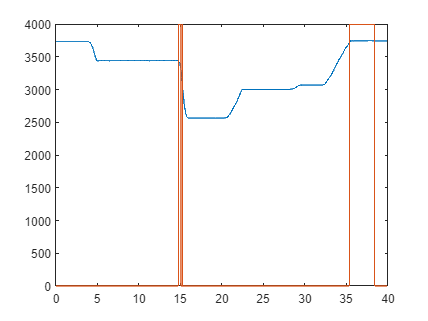

plot(t, yCam)
hold on
plot(t, 4000*bumper)
hold off